Set initial particle parameters

sizeInit = 0.00036% Initial particle size (m)

sizeInit = 3.6000e-04

rhoP = 1012% Particle density (kg.m⁻³)

rhoP = 1012

Create initial particle

rhoW = 1028 % Seawater density (kg.m⁻³)

rhoW = 1028

mpInit = MP(sizeInit, rhoP, rhoW, 0, 0);

Create aggregates with different fractal dimension and primary particle sizes values

D = 0:0.1:3; % Fractal dimension 
dp = [100:100:1000]*1e-6; % Primary particle size (m)

mpAgg(length(dp),length(D)) = MP; % array of aggregates
for idp = 1:length(dp)
    for iD = 1:length(D)
        mpAgg(idp,iD) = mpInit.aggregate(dp(idp),D(iD));
    end, clear iD,
end, clear idp,

Plot settling velocities

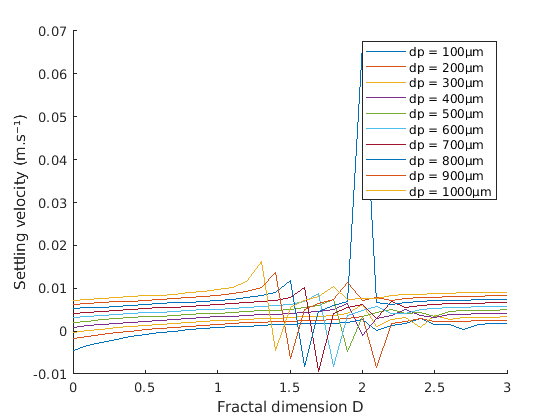

WsAgg = nan(length(dp),length(D)); % array of settling velocities
for idp = 1:length(dp)
    for iD = 1:length(D)
        WsAgg(idp,iD) = mpAgg(idp,iD).U_;
    end, clear iD,
end, clear idp,

figure,
hold on
for idp = 1:length(dp)
    plot(D,WsAgg(idp,:),'DisplayName',['dp = ' num2str(dp(idp)*1e6) 'µm'])
end, clear idp,
hold off
legend
xlabel('Fractal dimension D')
ylabel('Settling velocity (m.s⁻¹)')

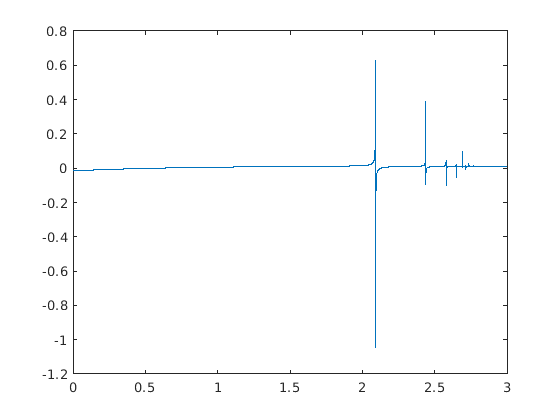

D = 0:0.001:3; % Fractal dimension 

U = nan(size(D));
for iD = 1:length(D)
    U(iD) = VitesseLiLogan(350e-6, 100e-6, D(iD), 0.01);
end, clear iD,

plot(D,U)

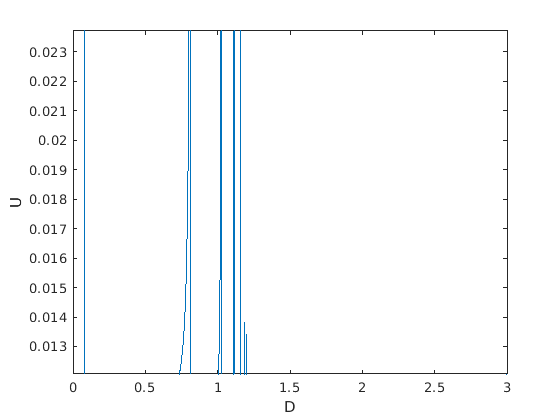

da = 350e-6;
dp = 300e-6;
Us = 0.01;
c = 0.25;

Porosity = nan(size(D));
for iD = 1:length(D)
    Porosity(iD) = 1 - c*(da/dp)^(D(iD)-3);
end, clear iD,
Kappa = dp^2/72 .* (3 + 3./(1-Porosity) - 3*sqrt(8./(1-Porosity)-3));

xi = da./(2.*sqrt(Kappa));
% Gamma = xi./(xi-tan(xi)) + 3./(2*xi.^2);
a = xi-tan(xi);
b =  3./(2*xi.^2);
Gamma = xi./a + b;
U = Gamma.*Us;

plot(D,U)
xlabel('D')
ylabel('U')
ylim(sort([U(1) U(end)]))